soft_folder = "soft_gripper_expts_2/";
soft_files = ["expt_2.mat";"expt_3.mat";"expt_5.mat";"expt_10.mat"];

rigid_folder = "rigid_gripper_expts_2/";
rigid_files = ["expt_1.mat";"expt_8.mat";"expt_9.mat"];

% plot variables here
titlefsz = 20;
textfsz = 17;
axfsz = 15;
linewidth = 2;

load("characteristic_2.mat");
k = k/2;
r = r/2;


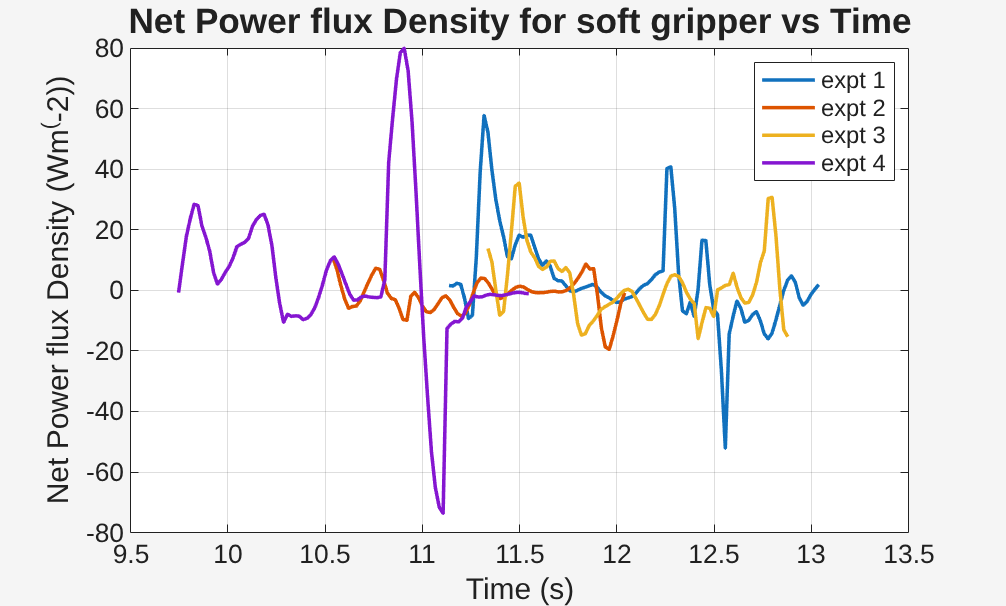

soft_max_pfd = zeros(4,1);
rigid_max_pfd = zeros(3,1);
soft_avg_pfd = zeros(4,1);
rigid_avg_pfd = zeros(3,1);

% in ot or at
rigid_contact_i = [386 494; 300 384; 362 461];
soft_contact_i = [451 546; 460 535; 537 614; 394 484];

figure;
theme(figure,"light");

for i = 1:4
    load(soft_folder + soft_files(i));
    
    i_start = soft_contact_i(i,1);
    i_end = soft_contact_i(i,2);

    zl = enc(i_start:i_end,1);
    zr = enc(i_start:i_end,2);

    zdl = diff(zl);
    zdl(end + 1) = zdl(end);
    zdl = zdl*50;
    zdl = lowpass(zdl,0.5);
    
    zdr = diff(zr);
    zdr(end + 1) = zdr(end);
    zdr = zdr*50;
    zdr = lowpass(zdr,0.5);

    otc = ot(i_start:i_end);
    fzl = -1*estimate_lattice_force(zl,otc,t_inv,k,r(1),r(2),kr);
    fzr = -1*estimate_lattice_force(zr,otc,t_inv,k,r(1),r(2),kr);
    
    al = area(1,i_start:i_end) + area(2,i_start:i_end) + area(3,i_start:i_end) + area(4,i_start:i_end);
    al = al';
    ar = area(5,i_start:i_end) + area(6,i_start:i_end) + area(7,i_start:i_end) + area(8,i_start:i_end);
    ar = ar';

    pfdl = (fzl .* zdl) ./al;
    pfdr = (fzr .* zdr) ./ar;
    pfd = pfdl + pfdr;
    plot(otc,pfd,"LineWidth",linewidth);
    hold on;
end

ax = gca;
ax.FontSize = axfsz;
xlabel("Time (s)","FontSize",textfsz);
ylabel("Net Power flux Density (Wm^(-2))","FontSize",textfsz);
title("Net Power flux Density for soft gripper vs Time","FontSize",titlefsz);
% xlim([9.31,11.1]);
% ylim([0,8]);
grid on;
legend(["expt 1" "expt 2" "expt 3" "expt 4"]);
% saveas(gcf,"soft_pfd_force.png");
hold off;

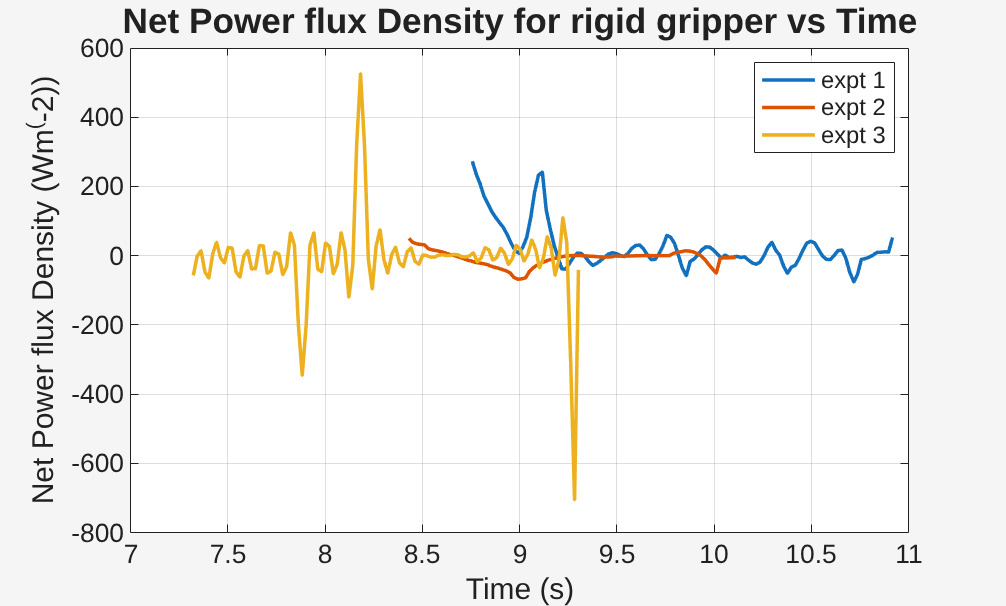

figure;
theme(figure,"light");

for i = 1:3
    load(rigid_folder + rigid_files(i));

    i_start = rigid_contact_i(i,1);
    i_end = rigid_contact_i(i,2);

    zl = enc(i_start:i_end,1);
    zr = enc(i_start:i_end,2);

    zdl = diff(zl);
    zdl(end + 1) = zdl(end);
    zdl = zdl*50;
    zdl = lowpass(zdl,0.5);

    zdr = diff(zr);
    zdr(end + 1) = zdr(end);
    zdr = zdr*50;
    zdr = lowpass(zdr,0.5);

    otc = ot(i_start:i_end);
    fzl = -1*estimate_lattice_force(zl,otc,t_inv,k,r(1),r(2),kr);
    fzr = -1*estimate_lattice_force(zr,otc,t_inv,k,r(1),r(2),kr);

    al = area(1,i_start:i_end) + area(2,i_start:i_end) + area(3,i_start:i_end) + area(4,i_start:i_end);
    al = al';
    ar = area(5,i_start:i_end) + area(6,i_start:i_end) + area(7,i_start:i_end) + area(8,i_start:i_end);
    ar = ar';
    
    ar = ar + 0.5e-4;
    al = al + 0.5e-4;

    pfdl = (fzl .* zdl) ./al;
    pfdr = (fzr .* zdr) ./ar;
    pfd = pfdl + pfdr;

    plot(otc,pfd,"LineWidth",linewidth);
    %plot(otc,ar);
    
    hold on;
end

ax = gca;
ax.FontSize = axfsz;
xlabel("Time (s)","FontSize",textfsz);
ylabel("Net Power flux Density (Wm^(-2))","FontSize",textfsz);
title("Net Power flux Density for rigid gripper vs Time","FontSize",titlefsz);
% xlim([9.31,11.1]);
% ylim([0,8]);
grid on;
legend(["expt 1" "expt 2" "expt 3"]);
saveas(gcf,"rigid_pfd_force.png");
hold off;

% plot(at,net_area',"LineWidth",linewidth,"Color",[0 0.5 0]);
% hold on;
% ax = gca;
% ax.FontSize = axfsz;
% xlabel('Time (s)','FontSize',textfsz);
% ylabel('Net Area (m^2)','FontSize',textfsz);
% title('Contact Area vs time','FontSize',titlefsz-2);
% xlim([0 25]);
% grid on;
% saveas(gcf,"Contact area over full experiment.png")
% hold off;